# APMA 2501 - Programming in R & MATLAB: MATLAB Unit 4

## **From Randomness to Simulations**

- Topic 1: Plinko Simulation

- Topic 2: Random Numbers

What we will do today:

- Plinko simulation and beam machine statistics

- Random numbers and implementation to the shared birthday problem

## MATLAB Copilot Topic #3: Get Code Explainations

MATLAB Copilot allows users to generate clear explainations of their selected code, as well as automatically inserting comments into their scripts. This feature allows users to better understand how their code works and identify potential problems/bugs in their scripts. Through this, MATLAB Copilot supports learning and collaboration, simplifying the process of reviewing, updating, and improving user code. 

Key tips and advice for getting code explainations:

- Select a small block, not the whole file. The explanation is usually much clearer than asking it to explain an entire script at once.

- Use some follow-up prompts after the first explanation. Copilot is designed for conversational follow-up in the chat panel.

## **MATLAB Copilot Topic #4: Get Error Explainations**

MATLAB Copilot enables users to get clear explainations on code errors, as well as suggest potential solutions. By analyzing the error as well as surrounding code, MATLAB Copilot provides explainations on code mistakes and troubleshooting tips, streamlining the debugging process. This allows users to quickly identify issues, as well as resolve them more efficiently, reducing overall debugging time. 

Key tips and advice for getting error explainations:

- Fix the earliest error first. Later errors are often just downstream effects, so asking Copilot about the first failure usually saves the most time.

- When debugging, ensure that you understand what Copilot is writing - Use the generate code explainations feature to assist you with this.

### More Tips and Tricks for MATLAB Copilot!

- **Use the integrated buttons:** For the fastest results, use the "Explain Error" button next to error messages or the right-click "Explain Code" action to save time on copying and pasting.

- **Leverage the chat for follow-ups:** If an explanation is too technical, ask Copilot to "simplify the explanation" or "provide a visual analogy" to better grasp the logic. Also, give Copilot context, not just the red text.

- **Verify against documentation:** While Copilot is grounded in official sources, always cross-reference its suggestions with your specific toolbox versions to ensure compatibility and accuracy.

## Topic 1: Plinko 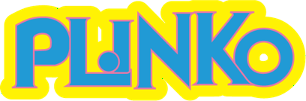

Plinko (also called a Galton Board) is a pegboard game where a disk or ball is dropped from the top and bounces off a regular array of pegs.

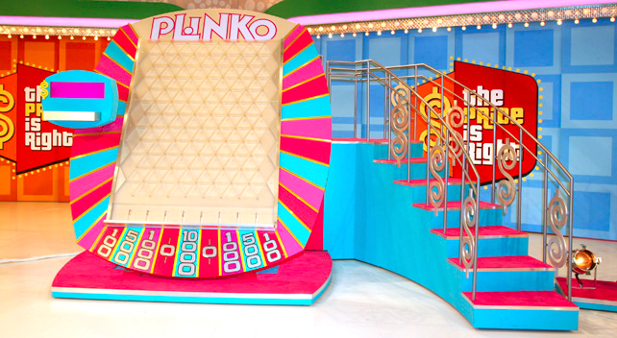

Two old YouTube videos of Plinko game recording:

- [http://youtu.be/E7DKxe_m1AM](http://youtu.be/E7DKxe_m1AM)

- [http://youtu.be/vuMir11YFPs](http://youtu.be/vuMir11YFPs)

#### Original idea from a device for statistical experiments - bean machine

The curve formed by the height of each bin approaches a normal distribution if the number of rows and balls is large.

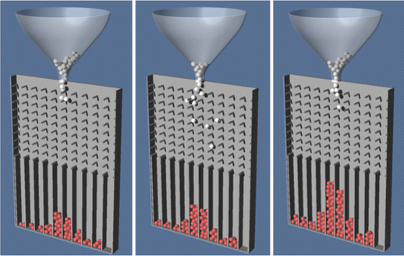

**Figure****:** Results of three different Galton Board experiments. Notice that all boards have the same number of rows (thus identical board arrangements), but the number of dropped balls in each case is different.

There is a variant of Galton Board in which only the nails that can potentially be hit by a ball dropped from the funnel are included, leading to a triangular array instead of a rectangular one.

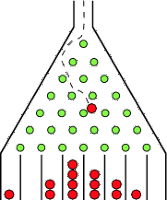

- Upright board with evenly spaced nails (or pegs)

- Nails are arranged in a staggered configuration

- Balls collected in heaps in evenly-spaced bins at bottom

- Each time a ball hits one of the nails, it can bounce right or left with equal probability

- If the number of balls is sufficiently large, the profile formed from the bin heights will approximate a normal distribution

#### Objective: s**imulate the bean machine for a given number of rows and released balls**

Some assumptions:

- No dropped ball goes outside of the board

- Subsequent to hitting a peg in one row, a ball can only interact with the peg immediately to the left or the right of that peg in the row below it

- A ball cannot fall through a row without interacting with a peg

- Balls fall directly into the bins after falling past the last row of pegs

### Small Example (5 rows & 6 bins):

If we only use 1 ball release point, then we have:

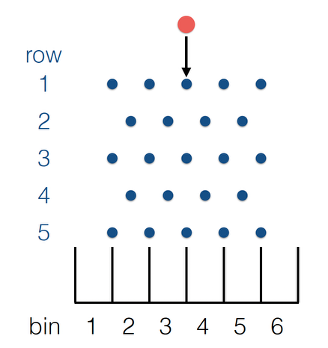

How do we determine the bin that a ball falls into? In a given row:

- Assign a 0 if ball moves left and 1 if ball moves right

- Add up the 0’s and 1’s from each row

- For a few examples, compare this sum with the bin number and see if a pattern emerges

What is the conclusion? -> *Collecting bin = sum of row moves {0,1} + 1  *[Think about how would this formula change if we used different release points instead of the middle?]

Now take a look at this code block below for computer simulation!

balls = 10000;
results = zeros(1,balls);
for i = 1:balls
    position = 0;
    for j = 1:6
        move = randi([0,1]);
            if move == 1
                position = position +1;
            end
    end
    results(i) = position;
end

% Plot results as a histogram
histogram(results)
xlabel('Value')
ylabel('Frequency')
title('Histogram of Ball Drops') 

***Explain Code:*** You may use this feature to learn new functions or logics in the code chunk! Select the line(s) by going to Live Editor -> Copilot -> Explain Code.

What does Copilot teach you through examples and explanations that you may not know otherwise (without prior knowledge or research). How can you see this expediting the learning process?

### Plinko Pseudocode

Provided is the general pseudocode for generating a bar chart displaying the results of a general plinko simulation.

% Set the number of rows in the board

% Set the number of collecting bins

% Initialize the array used to store bin counts

% Set the number of balls to simulate

% for k = 1:number of balls
    % Determine the final bin position of ball k
    
    % Add 1 to that bin’s count
% end

% Construct a bar chart with bin counts

## Topic 2: Random Numbers

Helpful MATLAB functions generating random numbers:

- `rand `returns a pseudorandom number

rand % generates a uniformly distributed pseudorandom number on the open interval (0,1) by default

- `randi(``imax``) `returns a pseudorandom integer between `1` and `imax`

imax = 5; randi(imax)

- `randi([``imin,imax``]) `returns a pseudorandom integer between `imin` and `imax`

randi([10, 5]) 

You will immediately see MATLAB throws red error text (as a regular error message). Click the **Explain Error** button underneath the error message and use Copilot's suggestions to fix the code.

randi([1,10], 10, 1)

- `randi([inim,imax],m,n) `returns a m-by-n array of pseudorandom integers in the interval `imin` and `imax`

### Testing for Randomness Statistically

What if we do it a lot of times? Note that the code below may not be entirely correct!

N =3000;              % number of samples
x = rand(N,1);            % uniform pseudorandom numbers on (0,1)
nbins = 10;               % number of bins
edges = linspace(0, 1, nbins+1);
counts = histcounts(x, edges);
bars = edges(1:end-1);

figure
bar(bars, counts, 0.8)
xlim([0 1])
xlabel('Value')
ylabel('Count')
title('Counts of 100 Uniform(0,1) Samples in 10 Bins')

***Explain Code:*** Use MATLAB Copilot to explain the line with `histcounts()`; also the line with the `bar()` function, which is another summary plot function!

### **Pseudo-**random Numbers

- Pseudorandom numbers are generated in sequences

- These sequences approximate sequences of truly random numbers

- An algorithm is used to generate a sequence of pseudorandom numbers

- This algorithm is initialized by a seed

- When a pseudorandom number generator is seeded, the sequence of numbers to be generated is fully established

### Seeding Random Number Generator 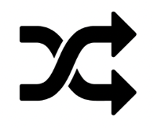

When you use the "shuffle" command on a music player, a seed is established and a pseudorandom sequence is generated.

- Pressing "previous" or "next" moves the player along the sequence

- A new sequence isn't created until "shuffle" is pressed again

In MATLAB, the default random seed is fixed for everyone, so is this a flaw?

It's actually useful since we can reproduce a specific random simulation if we know the seed. Every time MATLAB opens, the random number generator (`rng`) is seeded to the same default value so the results are reproducible.

rng('default') % rng(0)
% seeds to the default value so that the rng produces the same numbers as if you restarted MATLAB
rng(1)
rng(2)

And if you want your random numbers generated differently each time you run the code, you can use:

rng('shuffle')
% seeds the rng based on the current time leading to unpredictable results

This seeds the random number generator based on the current time, leading to different (non-reproducible) results each run.

*Note: you only need to do this step once at the beginning of your method!*

### Debugging Exercise

Oh no! This block of code below contains several critical errors. Using the references above, or MATLAB Copilot's ***Explain Error*** feature, identify what the problems are. 

There are three errors total. Some errors can run without issue, so please consider using MATLAB Copilot to explain the code, and check if they match to what they are supposed to do?

% [[[ LUCKY 7-11 GAME ]]]
% In this game, two dice are rolled independently.
% A win occurs when the sum is 7 or 11.
% Each win earns $2, and each game costs $1.
% We would like to see if this game is fair or not by simulation.
clc; clear; close all;
rng(1)

nGames = 1000;

die1 = randi([1 6], nGames, 1);
die2 = randi(1, 6, nGames, 1); 

totals = die1 + die2;

wins = (totals = 7) | (totals = 11);

profit = 2*wins - nGames; 
disp('Estimated total profit:')
disp(profit)

Notice that we have been using the "Explain code/error" feature today. Here are some follow up questions based on "Explain error":

- One of the more frustrating features of MATLAB errors is that for each code section, errors are displayed one at a time, meaning only one error can be explained at a time. But you may notice where the error message is placed in a break of the code section. How can you use this to infer where the error is?

- Copilot is very good at catching syntax errors because it is trained to recognize correct MATLAB usage. However, if you do not understand the mathematics and array operations behind your script, logic errors can still go unnoticed. What do you think would be the biggest benefit of this error explaination feature for your own coding?